## Question 1

A1 = [3 0; 0 -6];
A2 = [3 0.1; 0 -6];
B1 = [1;0];
B2 = [0;1];

Los teoremas 6 y 8 son "binarios", solo nos dan información de si es controlable o no. No obstante, el Teorema 7 nos da algo más de información sobre cuanto de controlable es el sistema. Para mirar si un sistema es estabilizable, hay que mirar el Teorema 9.

[vecA1t, eigA1t] = eig(A1')

vecA1t =      0     1
     1     0


eigA1t =     -6     0
     0     3


[vecA2t, eigA2t] = eig(A2')

vecA2t =          0    0.9999
    1.0000    0.0111


eigA2t =     -6     0
     0     3


Comprobamos la controlabilidad y estabilicidad de (A1,B1) acorde al Teorema 7

B1'*vecA1t

ans =      0     1


B1'*vecA1t(:,2)  % Miramos únicamente los autovectores pertenecientes a los eig positivos

ans = 1

Voy a comprobar también la controlabilidad de (A2, B2)

B2'*vecA2t

ans =     1.0000    0.0111


Fijaos que aunque sale controlable (ningún autovector de $A_2^T$ pertenece al kernel de $B_2^T$), el segundo término es más cercano a cero que el primero. Eso quiere decir que no tenemos "mucha autoridad", o que habrá que gastar mucha más energía, para controlar los estados en ese subespacio (que marca el segundo autovector de $A_2^T$).

## Question 2

Vamos a seguir la metodología de la sección 10.2. 

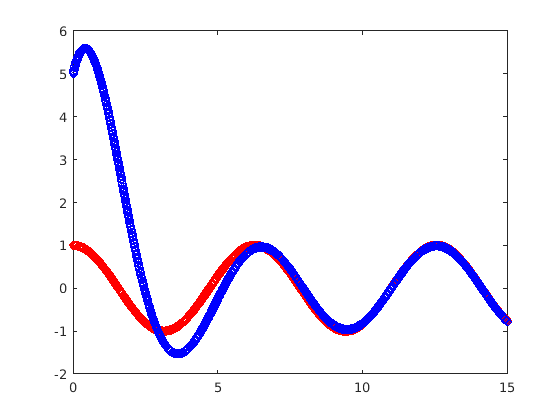

% Señales de referencia
dt = 0.01; % Paso de tiempo para luego integrar por Euler
tf = 15; % Tiempo final para la simulacion
t = 0:dt:tf;
ft = cos(t);
dft = -sin(t);
ddft = -cos(t);

% Condiciones iniciales arbitrarias
x1 = 5;
x2 = 3;

figure(1)
plot(0,x1,'ob')
hold on
plot(t,ft,'or') % pintamos la señal de referencia

% Simulamos el sistema
for t = dt:dt:tf
  % Construimos las señales de error y la entrada de control
  e1 = x1 - cos(t);
  e2 = x2 + sin(t);
  u = -cos(t) -e1 -e2; % Diseñado con Lyapunov
  
  % Integramos con método de Euler
  x2 = x2 + u*dt;
  x1 = x1 + x2*dt;
  
  % También se podría hacer
  % X = [x1;x2]
  % dotX = A*X + B*u
  % X = X + dotX * dt
  % con A = [0 1;0 0]  y B = [0 1]
  
  % Pintamos la posicion
  plot(t,x1,'ob')
end

## Question 3

Vamos a seguir la metodología de la sección 10.3

% Condición inicial
x1 = 3;
x2 = 5;
dotx1 = 0.3;
dotx2 = -0.5;

% Sistema
X = [x1; dotx1; x2; dotx2];
A = [0 1 0 0; 0 0 0 0; 0 0 0 1; 0 0 0 0];
B = [0 1 0 0; 0 0 0 1]';

% Tiempos para la simulación
dt = 0.01; % Tiempo de paso
tf = 10; % Tiempo final

% Pintamos la posición inicial en 2D
figure(2)
plot(x1,x2,'ob')
hold on

% Simulamos el sistema
for t = dt:dt:tf
  % Curvas de nivel del conjunto de puntos deseado
  phi = X(1)*X(1) + X(3)*X(3) - 1;
  e = phi;
  
  % Gradiente de las curvas de nivel
  nabla_phi_x1 = 2*X(1);
  nabla_phi_x2 = 2*X(3);
  grad_phi = [nabla_phi_x1 nabla_phi_x2]; % Gradientes son un vector fila! Jacobiano 
  
  % Sacamos la velocidad del punto
  pdot = [X(2); X(4)];
  
  % Construimos la señal de control
  u = -e*grad_phi' - 10*pdot;
  
  % Euler
  dotX = A*X + B*u;
  X = X + dotX *dt;

  % Pintamos la posición
  plot(X(1),X(3),'ob')
end
t = 0:0.01:2*pi;
plot(cos(t), sin(t),'r')
plot(X(1),X(3),'or')